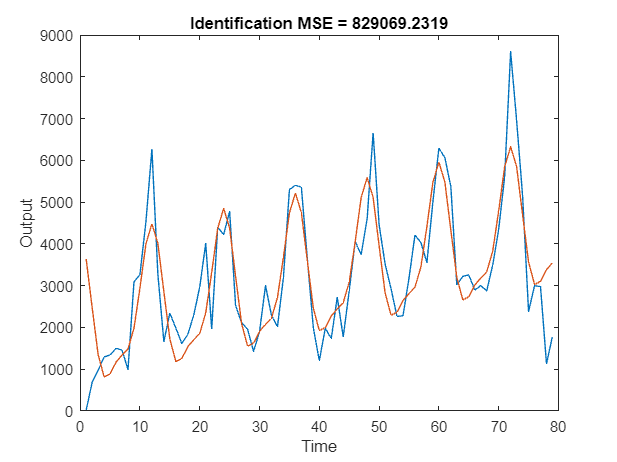

%PIECE WISE CONSTANT TREND IDENTIFICATION/APPROXIMATION
% aproximator polinomial
% chestii care sa aiba o aproximare mai buna a modelului
clear variables;

data = load("product_5.mat");

id = struct("t",data.time(1:79),"y",data.y(1:79));
val = struct("t",data.time(80:99),"y",data.y(80:99));

m = 2;
P = 12; % default period

%identification data
phi = zeros(length(id.y),2+2*m);
for line = 1:length(id.t) 
    phi(line,1) = 1;
    phi(line,2) = id.t(line);
    for regressor = 1:m
        phi(line,1+2*regressor) = cos(2*pi*regressor*id.t(line)/P);
        phi(line,2+2*regressor) = sin(2*pi*regressor*id.t(line)/P);
    end
end

y = id.y;
theta = phi\y;
y_hat = phi*theta;

mse = 1/length(id.t)*sum((y_hat-y).^2);

plot(id.t,id.y,id.t,y_hat); title("Identification MSE = " + string(mse));
xlabel("Time"); ylabel("Output");

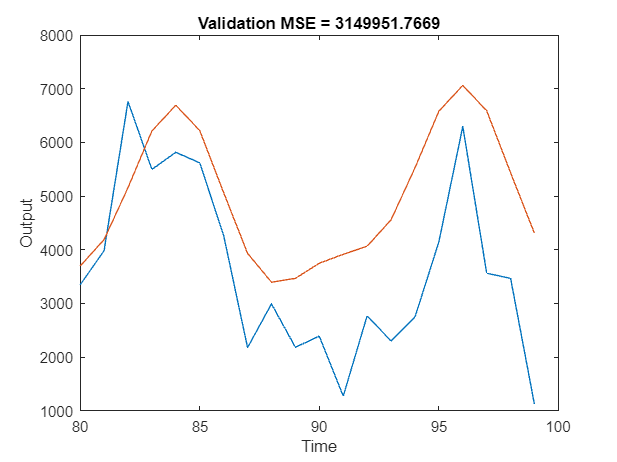


%validation data 
phi = zeros(length(val.y),2+2*m);
for line = 1:length(val.t) 
    phi(line,1) = 1;
    phi(line,2) = val.t(line);
    for regressor = 1:m
        phi(line,1+2*regressor) = cos(2*pi*regressor*val.t(line)/P);
        phi(line,2+2*regressor) = sin(2*pi*regressor*val.t(line)/P);
    end
end

y = val.y;
y_hat = phi*theta;

mse = 1/length(val.t)*sum((y_hat-y).^2);

plot(val.t,val.y,val.t,y_hat); title("Validation MSE = " + string(mse));
xlabel("Time"); ylabel("Output");